# Modelling, responses, analysis and feedback for a 1st order system

This note illustrates the use of MATLAB tools for a holistic modelling and control approach, but using the simplest example possible, a first order system, proportional control and then PI control. We illustrate a problem from the beginning to the end so, modelling, behaviour analysis and then control design.

- Generic background on 1st order model behaviours.

- Understand the roles of time constant and gain in modelling a system from a step response (assuming 1st order).

- Estimate parameters from an unseen system.

- Investigate the impact of proportional feedback on the closed-loop behaviour.

- Compare behaviour by overlaying a selection of responses for different gains.

- Experiment with a PI feedback design.

- Compare with heuristic PI designs.

You must have the symbolic and control toolboxes installed for this file to work.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Generic assumptions in this note and 1st order behaviours

- Modelling from data - generic principles

- Estimate model parameters from data: unseen example

- The impact of proportional control on a 1st order system: unity negative feedback

- Compare and contrast performance with a variety of compensator gains

-  Enter new values of PI gains and update the step response figures.

- Heuristic PI design

## 1. Generic assumptions in this note and 1st order behaviours

Assume that a first order model can be represented by a differential equation or transfer function as follows:


$$T\frac{\textrm{dx}}{\textrm{dt}}+x=C\;u;\;\;\;\;\;\;\;G\left(s\right)=\frac{C}{\textrm{Ts}+1}$$


For such systems we know that, with a constant input *u(t)=A*, the output is given as follows:


$$x\left(t\right)=\left\lbrack x\left(o\right)-\textrm{CA}\right\rbrack e^{-\frac{t}{T}} +\textrm{CA};\;\;\;\;\;\;\;\;u\left(t\right)=A$$


This curve has well know characteristics which link to the time constant T, for example:

$x\left(T\right)=\left\lbrack x\left(0\right)-\textrm{CA}\right\rbrack e^{-1} +\textrm{CA}=0\ldotp 37\left\lbrack x\left(0\right)-\textrm{CA}\right\rbrack +\textrm{CA}$;     37% from steady-state or 63% movement from *x(0)*.

$x\left(3T\right)=\left\lbrack x\left(0\right)-\textrm{CA}\right\rbrack e^{-3} +\textrm{CA}=0\ldotp 05\left\lbrack x\left(0\right)-\textrm{CA}\right\rbrack +\textrm{CA}$;     5% from steady-state or 95% movement from *x(0)*.

These key points can be used to construct a sketch of the step response using red vertical lines are drawn at T, 2T and 3T and green horizontal lines denotes 63%, 86% and 95% movement. Notice how the curve always goes through the intercepts [T,63%], [2T, 86%] and [3T, 95%], no matter what choices of *C, T, A* and* x(0)*.  This is shown in the figure here. 

You can define the required steady-state gain C, time constant *T*, input magnitude *A* and initial condition *x(0)* using the sliders below. 

C =0.6;
T =1.3;
x0 =1.7;
A =-2.7;

The current steady-state is given by CA (dotted black line), that is:

disp(['CA = ',num2str(C*A)])

CA = -1.62


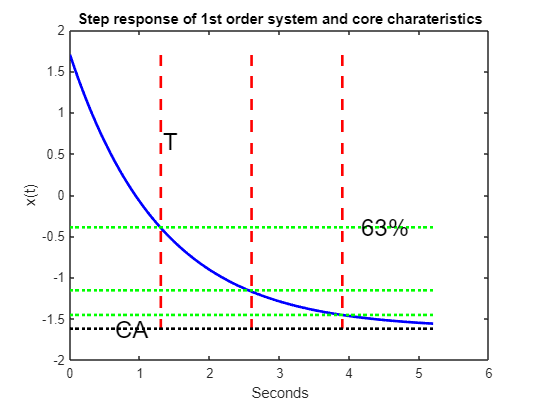

t=linspace(0,4*T,100);
x=(x0-C*A)*exp(-t/T) + C*A;
x63 = C*A+(x0-C*A)*.37; x86 = C*A+(x0-C*A)*.14; x95=C*A+(x0-C*A)*.05; 
a=figure;clf
plot(t,x,'b','linewidth',2); hold on
aa=plot([T,T],[x0,C*A],'r--',[2*T,2*T],[x0,C*A],'r--',[3*T,3*T],[x0,C*A],'r--');
bb=plot([0,4*T],[x63,x63],'g:',[0,4*T],[x86,x86],'g:',[0,4*T],[x95,x95],'g:',[0,4*T],[C*A,C*A],'k:');
set(bb,'linewidth',2);
set(aa,'linewidth',2);
xlabel('Seconds')
ylabel('x(t)')
text(T/2,C*A,'CA','fontsize',18);
text(T*1.02,x0+(x63-x0)*0.5,'T','fontsize',18)
text(T*3.2,x63,'63%','fontsize',18)
title('Step response of 1st order system and core charateristics')

disp('********* END OF introduction to 1st order behaviours *****************') 

********* END OF introduction to 1st order behaviours *****************


## 2. Modelling from data - generic principles

Given the first order model has such clear and simple characteristics, it is common in industrial practice to identify the parameters C and T from a step response, as first principles modelling is often difficult in practice (some things such as specific heats, heat loss coefficients and so forth can be hard to derive analytically for a real system).

One simple way of doing this (better methods will be covered in year 3) is by plotting a step response and:

- Identify the gain by recognising the steady-state is given by CA. For simplicity here assume the input is *u(t)=A=1*.

- Identifying the 63% movement point as this tells you the time constant. 

The figure below illustrates this process. Press the button to below generate a new random example and see how the lines are added to the figure to identify the core parameters. 

 
TT= round(rand(1)*10+5);
CC = round(randn(1)*20); if CC==0; CC=2;end
xx0 = round(randn(1)*10); if xx0==0; xx0=3;end; if xx0==CC; xx0=CC*2;end
tt=linspace(0,4*TT,100);
xx=(xx0-CC)*exp(-tt/TT) + CC;
xx63 = CC+(xx0-CC)*.37;
b=figure; clf
plot(tt,xx,'b','linewidth',2); hold on
title('Illustration of lines used to estimate time constant and gain')
plot([0,4*TT],[CC,CC],'k:','linewidth',2);
disp(['1. The steady-state is ',num2str(CC), ' which is also C given u(t)=A=1']);

1. The steady-state is -1 which is also C given u(t)=A=1


plot([0,4*TT],[xx63,xx63],'g:','linewidth',2);
text(TT*2.1,xx63,'63%','fontsize',18)
text(TT*1.02,xx0+(xx63-xx0)*0.5,'T','fontsize',18)
text(3*TT/2,CC,'C','fontsize',24);
disp(['2. Having marked the 63% movement point (green line), draw a red vertical line down from the intercept to find T']);

2. Having marked the 63% movement point (green line), draw a red vertical line down from the intercept to find T


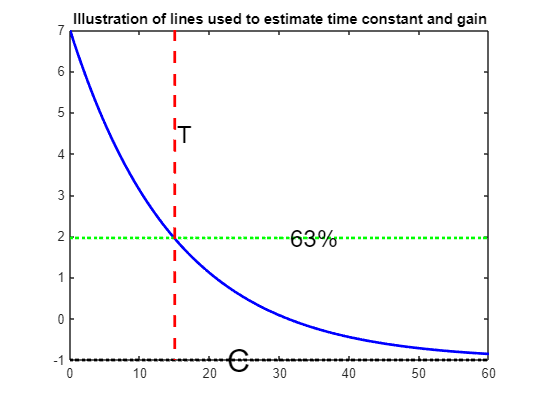

aa=plot([TT,TT],[xx0,CC],'r--','linewidth',2);

disp(['3. One can now see that the time constant is given as ', num2str(TT)])

3. One can now see that the time constant is given as 15


disp('********* END OF section 2 on generic modelling from data *****************')

********* END OF section 2 on generic modelling from data *****************


## 3. Estimate model parameters from data: unseen example needed for feedback design below

The feedback questions in the remainder of thie document, below this section, are based on the model underpinning this graph. 

You need to estimate the values for gain and time constant and enter in the boxes below. The figure will then be updated to include the step response of your model so you can check this against the true system.

TT= round(rand(1)*10+5);
CC = round(rand(1)*20); if CC==0; CC=2;end
xx0 = round(randn(1)*10); if xx0==0; xx0=3;end; if xx0==CC; xx0=CC*2;end
tt=linspace(0,4*TT,100);
xx=(xx0-CC)*exp(-tt/TT) + CC;


The figure below will update each time you change a guess so you can gradually improve your estimates.

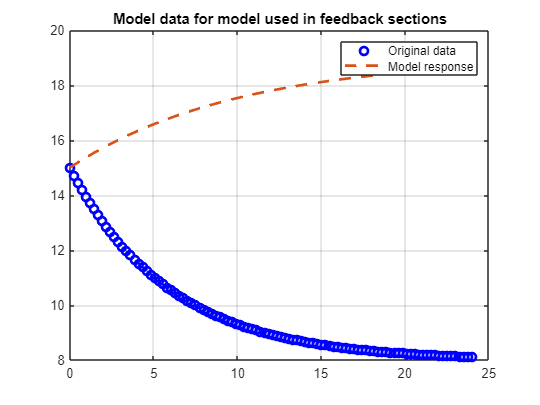

Cguess=19;
Tguess=10;
f=figure; clf
plot(tt,xx,'bo','linewidth',2); grid;hold on
title('Model data for model used in feedback sections')
xg=(xx0-Cguess)*exp(-tt/Tguess) + Cguess;
plot(tt,xg,'--','linewidth',2);
legend('Original data','Model response')

disp('********* END OF section 3 on modelling from data for example used below *****************')

********* END OF section 3 on modelling from data for example used below *****************


## 4. The impact of proportional control on a 1st order system: unity negative feedback

First consider unity negative feedback. Create closed-loop transfer functions with unity negative feedback, that is:


$$y=\frac{G}{1+G}r\;=G_c r,\;\;\;u=\frac{1}{1+G}r=G_{\textrm{cu}} r$$


Then plot the step responses. We assume the model is as defined in the top section so you can edit the model parameters there if desired. Several things are clear:

- Introducing feedback changes behaviour.

- The steady-state gain and the time constant of the closed-loop are very different from the open-loop.

- In truth, as we know open-loop is rarely satisfactory, one would not normal compare with the open-loop steady-state gain but the dynamics/poles are important.

- Unity negative feedback, that is K=1, is unlikely to deliver acceptable behaviour in terms of steady-state gain and possibly also speed of response.

Closed-loop transfer function Gc(s) with K = 1 is:

legendtext=cell(1);  %% for legend use later
legendtext{1}='open-loop';
legendtext{2}='K = 1';
G=tf(CC,[TT,1]);
Gc=feedback(G,1)   %% mapping target to output

Gc =
 
     8
  -------
  6 s + 9
 
Continuous-time transfer function.



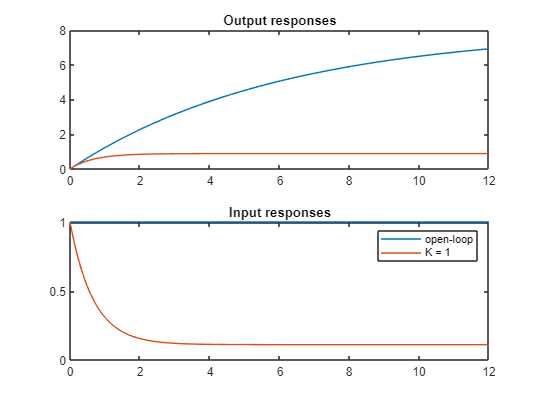

Gcu = feedback(1,G);  %% mapping target to input
[yo,to]=step(Gc,2*TT);
[uo]=step(Gcu,to);
[yo2]=step(G,to);

c=figure;clf
subplot(211)
plot(to,yo2); hold on
plot(to,yo);
title('Output responses')

subplot(212)
plot([0,2*TT],[1 1]); hold on
plot(to,uo);
legend(legendtext)
title('Input responses')

disp('********* END OF section 4 on impact of M = 1 proportional design *****************')

********* END OF section 4 on impact of M = 1 proportional design *****************


## 5. Compare and contrast performance with a variety of compensator gains

The previous section illustrated unity negative feedback and it was clear that, apart from anything else, the steady-state gain was poor. 

This section explores the potential of proportional feedback in general to deliver what we need by overlaying the closed-loop step response plots for a variety of different values of K - selected on the sliders below. Change these K and the section updates the figure automatically. Viewers should consider:

- Speed of response.

- Steady-state offsets.

- Input activity.

$y=\frac{\textrm{GK}}{1+\textrm{GK}}r\;=G_c r,\;\;\;u=\frac{K}{1+\textrm{GK}}r=G_{\textrm{cu}} r$,   $G_c =\frac{\textrm{KC}}{\textrm{Ts}+1+\textrm{KC}}$

K1 =0.1;   %% user choice of compensator gain
K2 =0.2;   %% user choice of compensator gain
K3 =0.8;   %% user choice of compensator gain
K4 =3.6;   %% user choice of compensator gain
K5 =8.5;   %% user choice of compensator gain


% Below here is the code you can ignore if you like
legendtext2{1}=['K1 = ',num2str(K1)];
legendtext2{2}=['K2 = ',num2str(K2)];
legendtext2{3}=['K3 = ',num2str(K3)];
legendtext2{4}=['K4 = ',num2str(K4)];
legendtext2{5}=['K5 = ',num2str(K5)];

disp('***********************************************************************')

***********************************************************************


Gc1=feedback(G*K1,1);
Gc2=feedback(G*K2,1);
Gc3=feedback(G*K3,1);
Gc4=feedback(G*K4,1);
Gc5=feedback(G*K5,1);
Gcu1 = feedback(K1,G);
Gcu2 = feedback(K2,G);
Gcu3 = feedback(K3,G);
Gcu4 = feedback(K4,G);
Gcu5 = feedback(K5,G);

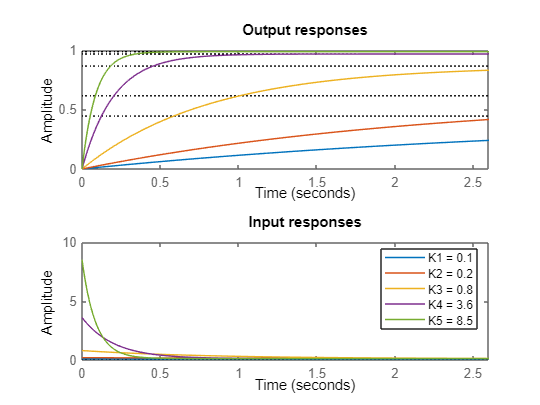

d=figure;clf
subplot(211)
step(Gc1,Gc2,Gc3,Gc4,Gc5,2*T);
title('Output responses')
subplot(212)
step(Gcu1,Gcu2,Gcu3,Gcu4,Gcu5,2*T);
legend(legendtext2)
title('Input responses')

Current offset for the different choices of Ki in order are:

off=[(1-dcgain(Gc1)),(1-dcgain(Gc2)),(1-dcgain(Gc3)),(1-dcgain(Gc4)),(1-dcgain(Gc5))];
disp(['Offset = ', num2str(round(100*off)),'   (All in %)'])

Offset = 56  38  14   3   1   (All in %)


disp('')
disp('***********************************************************************')

***********************************************************************



disp('********* END OF section 5 on impact of varied proportional design *****************')

********* END OF section 5 on impact of varied proportional design *****************


## 6. Enter new values of PI gains and update the step response figures

This section allows you to tune a PI compensator for the system defined in section 1. Also, this section has a memory function as long as you only modify the sliders which means you can overlay the step response plots for a variety of different values of* Kp* and* Ki *. Offset is expected to be zero with an integrator. 

**To clean the figure and begin again, set the sliders at the desired initial values and press 'clean figure'.**

The section assumes the following relationships hold, with M(s) the PI compensator. Use the sliders below the change the compensator values. The pole-zero map is avaiable in the following section.

$y=\frac{\textrm{GM}}{1+\textrm{GM}}r\;=G_c r,\;\;\;u=\frac{M}{1+\textrm{GM}}r=G_{\textrm{cu}} r$,   $M=K_p +\frac{K_i }{s}$

figure(c);clf
legendtext = legendtext(1:2);
subplot(211)
plot(to,yo2); hold on
plot(to,yo);
title('Output responses')

subplot(212)
plot([0,2*TT],[1 1]); hold on
plot(to,uo);
legend(legendtext)
title('Input responses')

Figure will update when you next change the sliders

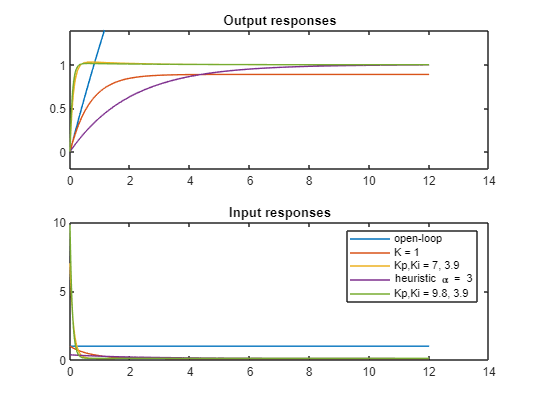

Kp =9.8;       %% user choice of proportional gain
Ki =3.9 ;   %% user choice of integral gain
M=tf([Kp,Ki],[1 0]);

% Below here is the code you can ignore if you like
legendtext{length(legendtext)+1}=['Kp,Ki = ',num2str(Kp),', ',num2str(Ki)];
%disp('***********************************************************************')
Gc=feedback(G*M,1);   %% mapping target to output
%disp('***********************************************************************')

Gcu = feedback(M,G);  %% mapping target to input
[y,t]=step(Gc,2*TT);
[u]=step(Gcu,t);

figure(c);
subplot(211)
plot(t,y); hold on
title('Output responses')
ylim([-0.2,1.4])

subplot(212)
plot(t,u); hold on
legend(legendtext)
title('Input responses')

### Create a figure window to allow display of pole and zeros using current PI compensator


f=figure;
disp(['Closed-loop transfer function Gc(s) with Kp, Ki = ',num2str(Kp),', ',num2str(Ki)])

Closed-loop transfer function Gc(s) with Kp, Ki = 7, 3.9


Gc

Gc =
 
      56 s + 31.2
  -------------------
  6 s^2 + 57 s + 31.2
 
Continuous-time transfer function.



p=pzmap(Gc);
disp(['Current closed-loop poles are at: ',num2str(p')])

Current closed-loop poles are at: -8.9168    -0.58317


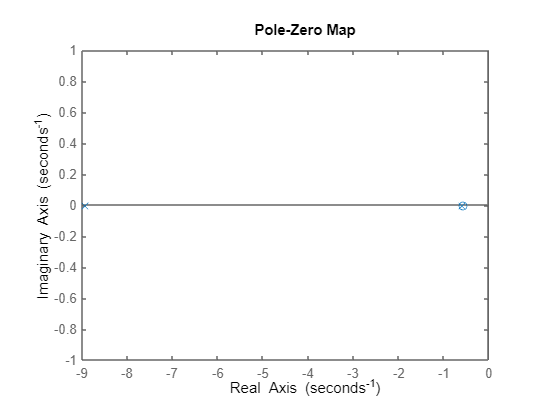


pzmap(Gc)

disp('********* END OF section 6 on impact of PI design *****************')

********* END OF section 6 on impact of PI design *****************


## 7. Heuristic PI design

A heuristic design of the PI tuning for a first order system is based on the desired speed up factor; how much faster $\alpha \;$than open-loop would you like to go. The tuning follows the rule:


$$K_p =\frac{\alpha }{G\left(0\right)};\;\;K_i =\frac{\alpha }{\textrm{TG}\left(0\right)}$$


For the current system we have the following values:

disp(['The current G(0) = ',num2str(C),'. The current T = ',num2str(T)]);

The current G(0) = 0.6. The current T = 1.3


Choose the desired speed-up and the corresponding Kp, Ki are computed below.

alpha =3;
Kp=alpha/CC;  Ki= Kp/TT;
disp(['For \alpha = ',num2str(alpha),' the heuristic choices are Kp = ',num2str(Kp),' and Ki = ',num2str(Ki)]);

For \alpha = 3 the heuristic choices are Kp = 0.375 and Ki = 0.0625


We can add this design to the PI plots of section above.

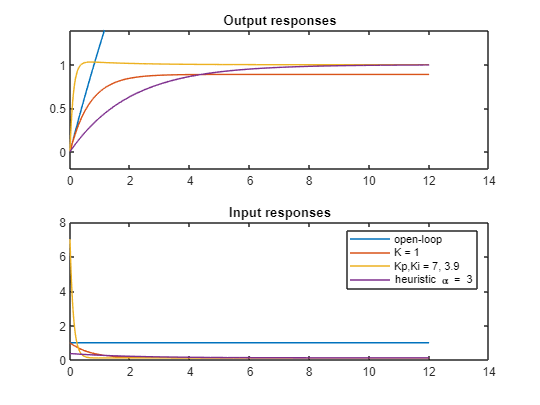

M=tf([Kp,Ki],[1 0]);
Gc = feedback(G*M,1);
Gcu=feedback(M,G);
legendtext{length(legendtext)+1}=['heuristic \alpha = ',num2str(alpha)];

[y]=step(Gc,t);
[u]=step(Gcu,t);

figure(c);
subplot(211)
plot(t,y); hold on
title('Output responses')

subplot(212)
plot(t,u); hold on
legend(legendtext)
title('Input responses')